# Display layer results

### Here we will check to see if our code does justice to a sample image from the dataset provided. This will be a sanity check for the main code!

% load cifar10testdata for getting the class labels
load 'cifar10testdata.mat'
% read truck image and resize it 
imrgb = imread("truck1.jpg");
imrgb = imresize(imrgb,[32, 32],'Method','bilinear');

Display sample image

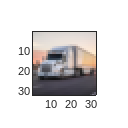

% %sample code to show image and access expected results
figure; imagesc(imrgb); truesize(gcf,[64 64]);

% run forward pass on the CNN model with input image 
import model.*
m = model();
output = m.forward(imrgb);

### Since the same functions have been called multiple times, we show the output for one random image through the same intermediate layers to verify the program's functioning.

% 1st Layer implementation [NORMALIZATION]
lets_norm = m.layerresults{1};
figure(3);
colormap("gray")

fprintf('Layer 1 Results,...');

Layer 1 Results,...

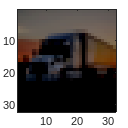

imagesc(lets_norm);

#### Convolution output visualization

% 2nd Layer implementation [CONVOLUTION]
lets_conv = m.layerresults{2};
figure(4);
colormap("gray")
fprintf('Layer 2 Results,...');

Layer 2 Results,...

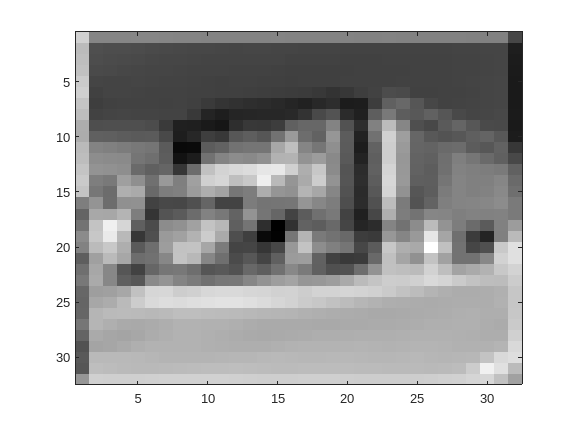

imagesc(lets_conv(:,:,1));

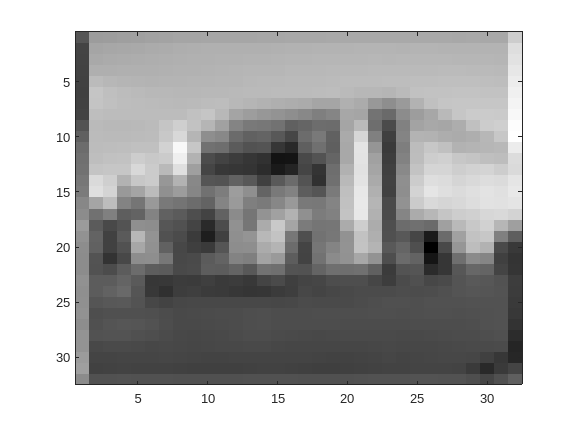

imagesc(lets_conv(:,:,5));

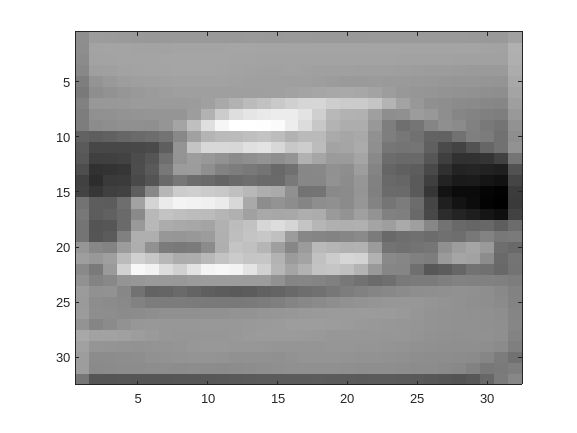

imagesc(lets_conv(:,:,10));

#### RELU output visualization

% 3rd Layer implementation [RELU]
lets_relu = m.layerresults{3};
figure(5);
colormap("gray")
fprintf('Layer 3 Results,...');

Layer 3 Results,...

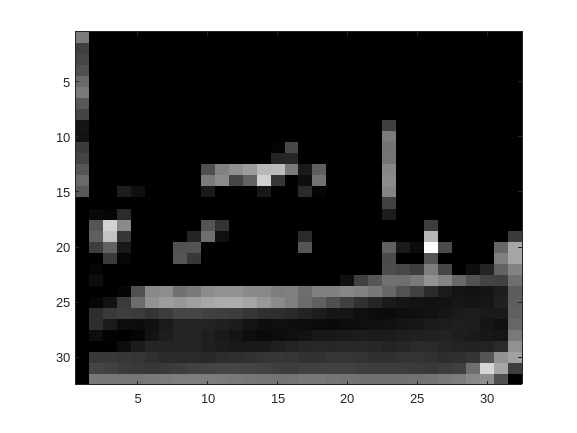

imagesc(lets_relu(:,:,1));

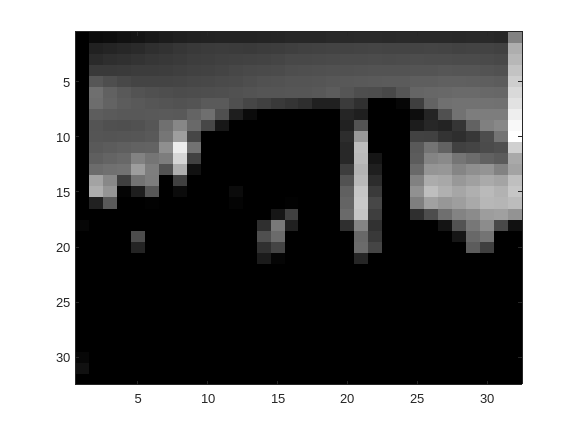

imagesc(lets_relu(:,:,5));

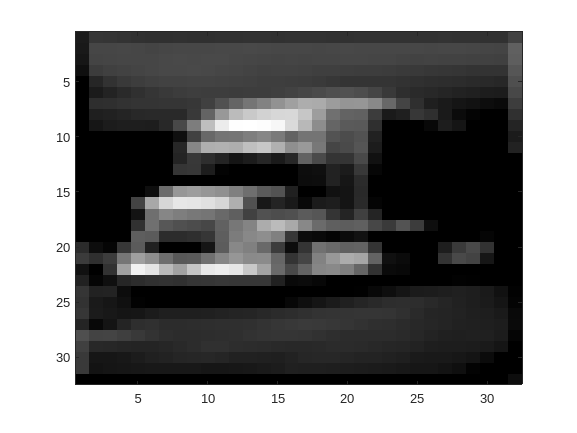

imagesc(lets_relu(:,:,10));

#### Maxpool output visualization

% 6th Layer implementation [MAXPOOL]
lets_maxpool = m.layerresults{6};
figure(6);
colormap("gray")

fprintf('Layer 6 Results,...');

Layer 6 Results,...

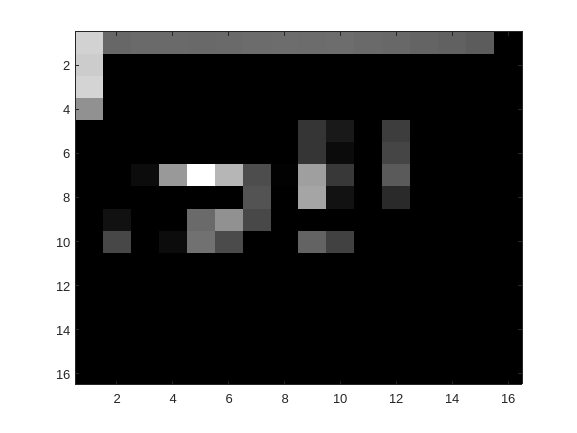

imagesc(lets_maxpool(:,:,1));

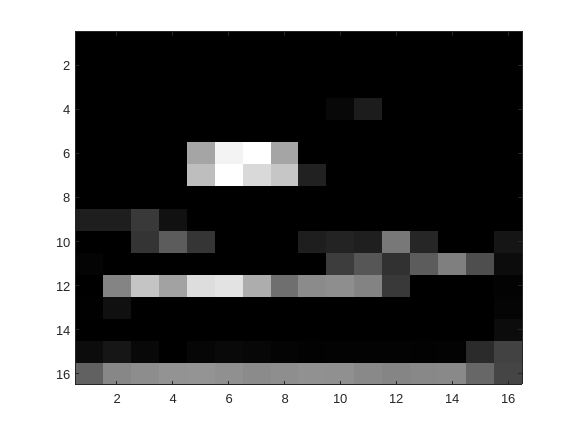

imagesc(lets_maxpool(:,:,5));

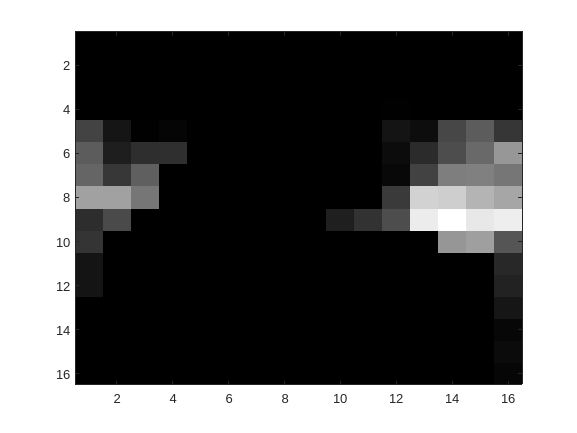

imagesc(lets_maxpool(:,:,10));

#### Softmax output visualization

% 18th Layer implementation [SOFTMAX]
lets_softmax = m.layerresults{18};
figure(8);
fprintf('Layer 18 Results,...');

Layer 18 Results,...

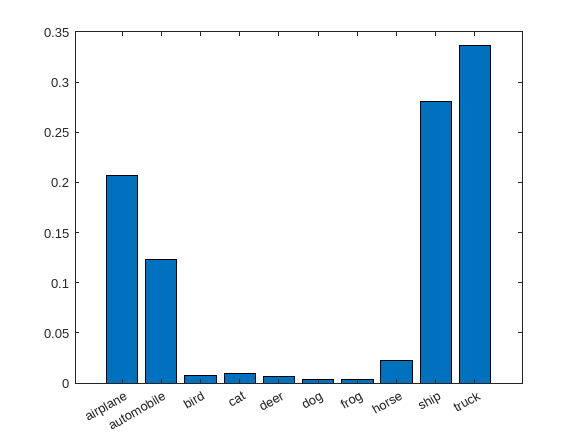

bar(squeeze(lets_softmax))
set(gca,'xticklabel',classlabels)